%Equipo 1
%Andrés Huerta Robinson A00838626
%Mauricio Gutierrez Treviño A00838011
clear
clf
%Variables segun las referencias
vel = 95 % Velocidad del vehículo en km/h

vel = 95

masa = 880; % Masa del vehiculo en kg
umbral_curvatura = .0026; % Umbral de la curvatura para identificar secciones de la curva
g = 9.81; % Aceleración debido a la gravedad en m/s^2
coeficiente_friccion = 1.5; % Coeficiente de fricción entre las ruedas y la superficie de la pista
desaceleracion = 49.05; % en m/s^2 ,Supongamos una desaceleración máxima de 5 g (49.05 m/s^2)

angulo = linspace(0, 2 * pi, 100);
angulo_peralte = 20; % Angulo del peralte en grados
theta_rad = deg2rad(angulo_peralte); % Convertir el ángulo de peralte a radianes

% Coeficientes de los polinomios
pInicial = [10, 290];
pFinal = [260, 180];

% Crear puntos intermedios
puntoIntermedio_1 = [150, 205];
puntoIntermedio_2 = [200, 250];

% Crear un vector de coordenadas X y Y para los puntos iniciales y finales
x_coords1 = [pInicial(1), pFinal(1)];
y_coords1 = [pInicial(2), pFinal(2)];

% Crear un vector de coordenadas X y Y que incluye los puntos iniciales, intermedios y finales
x_coords = [pInicial(1), puntoIntermedio_1(1), puntoIntermedio_2(1), pFinal(1)];
y_coords = [pInicial(2), puntoIntermedio_1(2), puntoIntermedio_2(2), pFinal(2)];

% Ajustar un polinomio de tercer grado a los puntos
grado = 3;
coef = polyfit(x_coords, y_coords, grado);

f = @(x) coef(1)*x.^3 + coef(2)*x.^2 + coef(3)*x + coef(4);

df = @(x) 3 * coef(1) * x.^2 + 2 * coef(2) * x + coef(3);
ddf = @(x) 6 * coef(1) * x + 2 * coef(2);

longitud_arco = integral(@(x) sqrt(1 + (3 * coef(1) * x.^2 + 2 * coef(2) * x + coef(3)).^2), pInicial(1), pFinal(1));

% Verificar si la longitud del arco cumple con los requisitos
if longitud_arco > 300 && longitud_arco < 500
    fprintf('La longitud del arco es %f m.\n', longitud_arco);
else
    fprintf('La longitud del arco no cumple con los requisitos.\n');
end

La longitud del arco es 430.668756 m.



p = 100;
x = linspace(pInicial(1), pFinal(1), p);
y = @(x) coef(1)*x.^3 + coef(2)*x.^2 + coef(3)*x + coef(4);

curvaturamin = inf;

% Calcular la curvatura mínima y el radio de curvaturacurvaturamin = inf;
radiocurvatura = zeros(1, p); % Inicializar un vector para almacenar los radios de curvatura

% Calcular la curvatura mínima y el radio de curvatura
for i = 2:p-1
    curvatura = abs(ddf(x(i))) / (1 + df(x(i))^2)^(3/2); % Fórmula de la curvatura

    curvaturamin = min(curvaturamin, curvatura);
    radiocurvatura(i) = 1 / curvatura; % Calcular el radio de curvatura en cada punto
end
radiocurvatura = 1 / curvaturamin;

% Verificar si el radio de curvatura cumple con el requisito
if radiocurvatura < 50
    fprintf('El radio de curvatura es %f m.\n', curvatura);
    fprintf('Su curvatura mínima es de %f m.\n', curvaturamin);
end

puntos_inflexion = [];

% Encontrar los puntos de inflexión 
for i = 2:p-1
    if sign(ddf(x(i-1))) ~= sign(ddf(x(i)))
        puntos_inflexion = [puntos_inflexion, x(i)];
    end
end

puntos_criticos = roots([3 * coef(1), 2 * coef(2), coef(3)]);
y_puntos_criticos = f(puntos_criticos);

radios_curvatura = 1 ./ abs(2 * coef(1) * puntos_criticos + 2 * coef(2));

punto_critico1 = [puntos_criticos(2)];
punto_critico2 = [puntos_criticos(1)];

radio1 = radios_curvatura(1);
radio2 = radios_curvatura(2);

% Calcular la altura adicional debido al peralte
altura_peralte = g * sin(theta_rad);

fprintf('Coeficiente de fricción usado: %f\n', coeficiente_friccion);

Coeficiente de fricción usado: 1.500000



% Cálculo de la velocidad máxima con peralte considerando fricción
vmax1_con_peralte_friccion = sqrt((radio1 * g)*(-sin(radio1)-coeficiente_friccion*cos(radio1))/cos(radio1)-coeficiente_friccion*sin(radio1));
vmax1_con_peralte_friccion_kmh = vmax1_con_peralte_friccion * 3.6; % Convertir a km/h
fprintf('Velocidad máxima con peralte y fricción en punto mínimo: %f km/h\n', vmax1_con_peralte_friccion_kmh);

Velocidad máxima con peralte y fricción en punto mínimo: 92.054982 km/h



vmax2_con_peralte_friccion = sqrt((radio2 * g)*(-sin(radio2)-coeficiente_friccion*cos(radio2))/-sin(radio2)-coeficiente_friccion*sin(radio2));
vmax2_con_peralte_friccion_kmh = vmax2_con_peralte_friccion * 3.6; % Convertir a km/h
fprintf('Velocidad máxima con peralte y fricción en punto mínimo: %f km/h\n', vmax2_con_peralte_friccion_kmh);

Velocidad máxima con peralte y fricción en punto mínimo: 67.685139 km/h



% Inicialización de variables para almacenar puntos de inicio y fin de cada sección de curva
puntos_inicio_curva = [];
puntos_fin_curva = [];
flag_seccion = false; % Variable para marcar si está dentro de una sección de curva
contador_puntos = 0; % Contador de secciones de curva encontradas

% Bucle para recorrer la pista y detectar las secciones de curva
for i = 2:p-1
    % Cálculo de la curvatura en el punto actual
    curvatura_actual = abs(ddf(x(i))) / (1 + df(x(i))^2)^(3/2);

    % Verificar si la curvatura supera el umbral y si no está dentro de una sección de curva
    if curvatura_actual > umbral_curvatura && ~flag_seccion
        puntos_inicio_curva = [puntos_inicio_curva, x(i)]; % Marcar el punto como inicio de la curva
        flag_seccion = true; % Indicar que está dentro de una sección de curva
        contador_puntos = contador_puntos + 1; % Incrementar el contador de secciones
    % Verificar si la curvatura no supera el umbral y si está dentro de una sección de curva
    elseif curvatura_actual <= umbral_curvatura && flag_seccion
        puntos_fin_curva = [puntos_fin_curva, x(i)]; % Marcar el punto como fin de la curva
        flag_seccion = false; % Indicar que ha salido de la sección de curva
    end
end

% Manejar el caso cuando la última sección termina al final de la pista
if flag_seccion
    puntos_fin_curva = [puntos_fin_curva, pFinal(1)]; % Añadir el último punto como fin de la curva
end

% Calcular el número de secciones de curva encontradas
num_secciones = length(puntos_inicio_curva);

% Inicializar vector para almacenar longitudes de secciones de curva
longitudes_secciones = zeros(1, num_secciones);

% Calcular la longitud de cada sección de curva mediante integración
for k = 1:num_secciones
    % Calcular la longitud de la sección de curva utilizando la función integral
    longitud_seccion = integral(@(x) sqrt(1 + (3 * coef(1) * x.^2 + 2 * coef(2) * x + coef(3)).^2), puntos_inicio_curva(k), puntos_fin_curva(k));
    longitudes_secciones(k) = longitud_seccion; % Almacenar la longitud de la sección
    fprintf('Longitud de la sección %d: %f m\n', k, longitud_seccion); % Imprimir la longitud de la sección
end

Longitud de la sección 1: 145.962766 m
Longitud de la sección 2: 150.828574 m


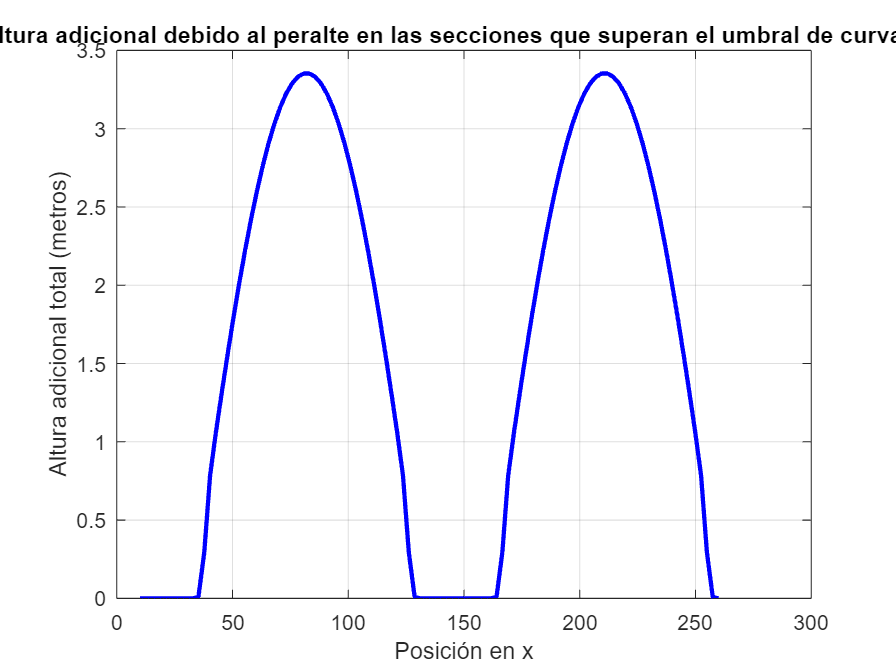


for i = 2:p-1
    curvatura_actual = abs(ddf(x(i))) / (1 + df(x(i))^2)^(3/2);

    if curvatura_actual > umbral_curvatura
        puntos_inicio_curva = [puntos_inicio_curva, x(i)];
    end
end

% Definir las alturas máximas de peralte para cada sección de la pista
alturas_maximas = [altura_peralte, altura_peralte]; % Ajusta las alturas máximas según cada sección

% Inicializar la altura del peralte en toda la pista
elevacion_total = zeros(1, p);


for k = 1:num_secciones
    % Definir las características de la sección actual
    x_inicio = puntos_inicio_curva(k);
    x_fin = puntos_fin_curva(k);
    altura_maxima = alturas_maximas(k);
    transition_length = 0.1 * (x_fin - x_inicio); % Longitud de transición para la disminución
    
    % Definir la función sinusoidal para el peralte en cada sección
    peralte_seccion = @(x) altura_maxima * (sin(pi * (x - x_inicio) / (x_fin - x_inicio))) .* ...
        ((x >= x_inicio & x <= x_fin));
    
    % Función logística para suavizar la transición al aumentar la elevación
    transition_up = @(x) (1 + tanh(3.5 * ((x - x_inicio - transition_length/2) / (transition_length/2)))) / 2;

    % Función logística inversa para suavizar la transición al disminuir la elevación
    transition_down = @(x) (1 + tanh(-3.5 * ((x - x_fin + transition_length/2) / (transition_length/2)))) / 2;

    % Calcular la elevación adicional en los puntos con peralte en la sección actual
    for i = 2:p-1
        if x(i) >= x_inicio && x(i) <= x_fin
            if x(i) <= (x_inicio + transition_length)
                elevacion_total(i) = elevacion_total(i) + peralte_seccion(x(i)) * transition_up(x(i));
            else
                elevacion_total(i) = elevacion_total(i) + peralte_seccion(x(i)) * transition_down(x(i));
            end
        end
    end
end

% Graficar la elevación adicional total en una sola gráfica
figure;
plot(x, elevacion_total, 'b-', 'LineWidth', 2);
title('Altura adicional debido al peralte en las secciones que superan el umbral de curvatura');
xlabel('Posición en x');
ylabel('Altura adicional total (metros)');
grid on;


velocidad_primera_curva = vel; % ajusta según el punto
radio_primera_curva = radio1; % ajusta según el punto

fuerza_centripeta_1 = (masa * velocidad_primera_curva^2) / radio_primera_curva;
fuerza_friccion_1 = coeficiente_friccion * masa * 9.81; % 9.81 m/s^2 es la aceleración debido a la gravedad

% Para la primera curva
% Verificar si el vehículo derrapará en la primera curva
if vel > vmax1_con_peralte_friccion_kmh
if fuerza_centripeta_1 > fuerza_friccion_1
    fprintf('El vehículo derrapará en la primera curva.\n');
    % Calcula la distancia de derrape desde el punto crítico
    punto_critico1 = punto_critico1(1); % Obtener solo la coordenada x del punto crítico

    pendiente_critico1 = df(punto_critico1);
    pendiente_mas10 = df(punto_critico1 + 10);
    pendiente_menos10 = df(punto_critico1 - 10);
   
    velocidad_derrape_1 = sqrt((fuerza_friccion_1 * radio_primera_curva) / masa);
    distancia_derrape_1 = (velocidad_primera_curva^2 ) / (2 * desaceleracion*coeficiente_friccion);

    % Calcula las coordenadas x e y del punto de derrape
    x_derrape_1 = punto_critico1 + distancia_derrape_1;
    y_derrape_1 = f(punto_critico1) + pendiente_critico1 * distancia_derrape_1;

    x_derrape_mas10 = punto_critico1 + 10 + distancia_derrape_1;
    y_derrape_mas10 = f(punto_critico1 + 10) + pendiente_mas10 * distancia_derrape_1;

    x_derrape_menos10 = punto_critico1 - 10 + distancia_derrape_1;
    y_derrape_menos10 = f(punto_critico1 - 10) + pendiente_menos10 * distancia_derrape_1;

fprintf('Distancia de derrape en la primera curva: %f metros\n', distancia_derrape_1);
    
else
    fprintf('El vehículo no derrapará en la primera curva.\n');
end
end

El vehículo derrapará en la primera curva.


Distancia de derrape en la primera curva: 61.331974 metros



% Para la segunda curva
velocidad_segunda_curva = vel; % ajusta según el punto
radio_segunda_curva = radio2; % ajusta según el punto

fuerza_centripeta_2 = (masa * velocidad_segunda_curva^2) / radio_segunda_curva;
fuerza_friccion_2 = coeficiente_friccion * masa * 9.81; % 9.81 m/s^2 es la aceleración debido a la gravedad

% Verificar si el vehículo derrapará en la segunda curva
if vel > vmax2_con_peralte_friccion_kmh
if fuerza_centripeta_2 > fuerza_friccion_2
    fprintf('El vehículo derrapará en la segunda curva.\n');

    punto_critico2 = punto_critico2(1); % Obtener solo la coordenada x del punto crítico

    pendiente_critico2 = df(punto_critico2);
    pendiente_mas10_2 = df(punto_critico2 + 10);
    pendiente_menos10_2 = df(punto_critico2 - 10);
    
    velocidad_derrape_2 = sqrt((fuerza_friccion_1 * radio_primera_curva) / masa);
    distancia_derrape_2 = (velocidad_primera_curva^2) / (2 * desaceleracion*coeficiente_friccion);

    % Calcula las coordenadas x e y del punto de derrape para la segunda curva
    x_derrape_2 = punto_critico2 + distancia_derrape_2;
    y_derrape_2 = f(punto_critico2) + pendiente_critico2 * distancia_derrape_2;

    x_derrape_mas10_2 = punto_critico2 + 10 + distancia_derrape_2;
    y_derrape_mas10_2 = f(punto_critico2 + 10) + pendiente_mas10_2 * distancia_derrape_2;

    x_derrape_menos10_2 = punto_critico2 - 10 + distancia_derrape_2;
    y_derrape_menos10_2 = f(punto_critico2 - 10) + pendiente_menos10_2 * distancia_derrape_2;

else
    fprintf('El vehículo no derrapará en la segunda curva.\n');
end
end

El vehículo derrapará en la segunda curva.



% Graficar el tramo de la pista
figure;
plot(x_coords1, y_coords1, '--o', 'color', 'k');
hold on;
plot(x_coords, y_coords, '--o', 'color', 'r');

x = linspace(pInicial(1), pFinal(1), 1000); % Genera un vector x con 1000 puntos entre pInicial(1) y pFinal(1)
y_polynomial = f(x); % Evalúa el polinomio en los puntos del vector x

road_color = [0.7, 0.7, 0.7]; % Cambia el color de la calle
plot(x, y_polynomial, 'Color', road_color, 'LineWidth', 5); % Ajusta el grosor de la línea de la calle

plot(x, y_polynomial, 'Color', 'yellow', 'LineStyle', '--', 'LineWidth', 1.5) % Grafica el polinomio



% Imprime los valores y en los puntos críticos 1 y 2
fprintf('Valor y en el punto crítico 1: %f\n', y_puntos_criticos(1));

Valor y en el punto crítico 1: 251.067659


fprintf('Valor y en el punto crítico 2: %f\n', y_puntos_criticos(2));

Valor y en el punto crítico 2: 145.700935



% Imprime los radios de curvatura en los puntos críticos 1 y 2
fprintf('Radio de curvatura en el punto crítico 1: %f m\n', radios_curvatura(1));

Radio de curvatura en el punto crítico 1: 20.628342 m


fprintf('Radio de curvatura en el punto crítico 2: %f m\n', radios_curvatura(2));

Radio de curvatura en el punto crítico 2: 13.283477 m


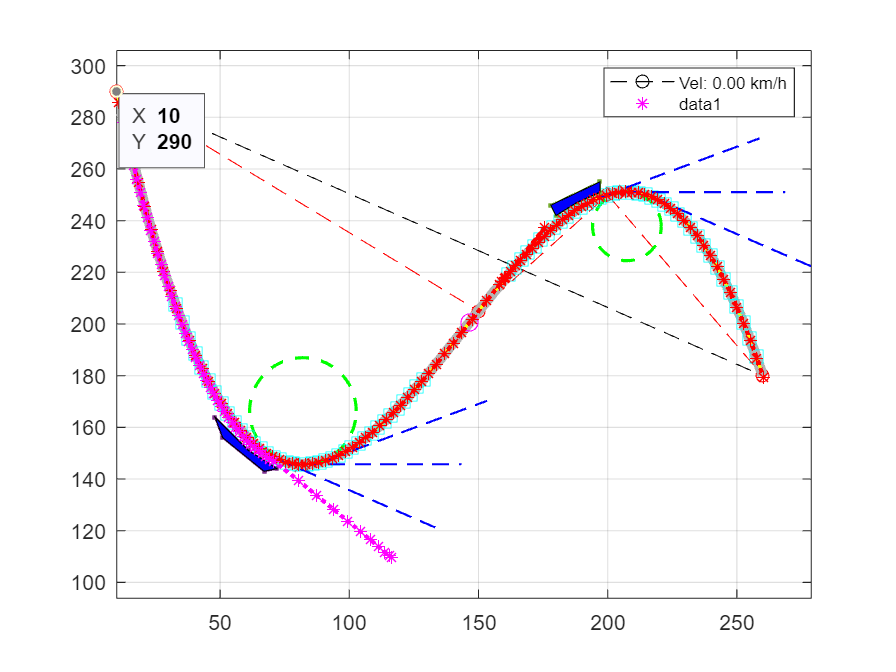

distanciad = 72.5952


plot(puntos_criticos, f(puntos_criticos), 'rx', 'MarkerSize', 10); % Grafica puntos crítico

% Bucle para graficar círculos en puntos críticos
for i = 1:length(puntos_criticos)
    % Calcula las coordenadas de un círculo en el punto crítico 1
    circulo_x = radio1 * cos(angulo) + punto_critico1(1);
    circulo_y = radio1 * sin(angulo) + f(puntos_criticos(2))+radio1;

     % Calcula las coordenadas de un círculo en el punto crítico 2
    circulo_x2 = radio2 * cos(angulo) + punto_critico2(1);
    circulo_y2 = radio2 * sin(angulo) + f(puntos_criticos(1))-radio2;

    % Grafica los círculos tangentes como líneas punteadas verdes
    plot(circulo_x, circulo_y, 'g--', 'LineWidth', 1.5);
    plot(circulo_x2, circulo_y2, 'g--', 'LineWidth', 1.5);
end

plot(puntos_inflexion, f(puntos_inflexion), 'mo', 'MarkerSize', 8); % Grafica puntos de inflexión
plot(puntos_inicio_curva, f(puntos_inicio_curva), 'cs', 'MarkerSize', 8); % Grafica puntos de inicio de curva

% Condicional del punto 1 para graficar líneas punteadas azules si se cumple la condición de velocidad y fuerza centrípeta
if vel > vmax1_con_peralte_friccion_kmh
if fuerza_centripeta_1 > fuerza_friccion_1
    line([punto_critico1, x_derrape_1], [f(punto_critico1), y_derrape_1], 'Color', 'b', 'LineStyle', '--', 'LineWidth', 1);
    line([punto_critico1 + 10, x_derrape_mas10], [f(punto_critico1 + 10), y_derrape_mas10], 'Color', 'b', 'LineStyle', '--', 'LineWidth', 1);
    line([punto_critico1 - 10, x_derrape_menos10], [f(punto_critico1 - 10), y_derrape_menos10], 'Color', 'b', 'LineStyle', '--', 'LineWidth', 1);
end
end

% Condicional del punto 2 para graficar líneas punteadas azules si se cumple la condición de velocidad y fuerza centrípeta
if vel > vmax2_con_peralte_friccion_kmh
if fuerza_centripeta_2 > fuerza_friccion_2
    line([punto_critico2, x_derrape_2], [f(punto_critico2), y_derrape_2], 'Color', 'b', 'LineStyle', '--', 'LineWidth', 1);
    line([punto_critico2 + 10, x_derrape_mas10_2], [f(punto_critico2 + 10), y_derrape_mas10_2], 'Color', 'b', 'LineStyle', '--', 'LineWidth', 1);
    line([punto_critico2 - 10, x_derrape_menos10_2], [f(punto_critico2 - 10), y_derrape_menos10_2], 'Color', 'b', 'LineStyle', '--', 'LineWidth', 1);
end
end
%Gradas
%Posicionadas para evitar el area de colision de los carros
%Y para darle buena vista de la accion al espectador
%Grada 1
pt1x = [72,61,48,51,67,72];
pt1y = [144,151,164,156,143,144];
plot(pt1x, pt1y, '.-', 'LineWidth', 1);  % '.-' conecta los puntos con linea
fill(pt1x, pt1y, 'b', 'FaceAlpha', 1); %llena la figura. facealpha = opacidad 0-1

%Grada 2
pt2x = [197,188,180,178,197,197];
pt2y = [251,247,242,246,255,251];
plot(pt2x, pt2y, '.-', 'LineWidth', 1);  % '.-' conecta los puntos con linea
fill(pt2x, pt2y, 'b', 'FaceAlpha', 1); %llena la figura. facealpha = opacidad 0-1

xm = linspace(8, pFinal(1)-2 , 100); % Genera un vector x con 1000 puntos entre pInicial(1) y pFinal(1)
y_polynomial = f(xm); % Evalúa el polinomio en los puntos del vector x

% Inicialización de variables para simulacion del vehiculo
dt = 0.1; % Intervalo de tiempo
Xin = xm(end); % Posición final en x
xi = xm(i); % Posición inicial en x
peralte = theta_rad; % Ángulo de peralte
miu = coeficiente_friccion; % Coeficiente de fricción
velocidad_actual_kmh = 0; % Inicializar la velocidad del vehículo en km/h
factor_reduccion_curva = .99; % Puedes ajustar este valor según la reducción de velocidad que desees aplicar
esta_en_peralte = false;


xn = xi; % Utilizar directamente el valor inicial como punto de inicio
yn = f(xi); % Utilizar el primer valor del polinomio para la posición y inicial

% Crear figura para la animación
ruta = animatedline('LineStyle', ':', 'LineWidth', 2, 'Color', 'r');

index = 1; % Índice para recorrer los valores de x e y_polynomial
while xn < Xin && index <= length(xm)
    % Obtener los valores de la posición x e y desde los vectores x e y_polynomial
    xn = xm(index);
    yn = y_polynomial(index);
    
    % Calcular la derivada primera (pendiente) en la posición actual
    derivada_primera = df(xn);
    
    Ra = (1 + derivada_primera^2)^(3/2) / abs(ddf(xn));
    alpha = atan(derivada_primera);
    % Verificar si el vehículo está en una sección con peralte
    for k = 1:num_secciones
        if xn >= puntos_inicio_curva(k) && xn <= puntos_fin_curva(k)
            esta_en_peralte = true;
            break;
        else
            esta_en_peralte = false;
        end
    end
    
    % Calcular la velocidad según si el vehículo está en una sección con peralte o no
    if esta_en_peralte
        Va = sqrt(Ra * g * (sin(peralte) + miu * cos(peralte) / cos(peralte) - miu * sin(peralte)));
    else
        Va = sqrt(Ra * g * miu);
    end
    
    % Verificar si el vehículo está en una curva
    if en_curva(xn, puntos_inicio_curva, puntos_fin_curva)
        % Lógica para controlar la velocidad dentro de una curva
        % Reducción de velocidad al entrar en una curva (ejemplo de lógica)
        Va = (Va * factor_reduccion_curva);
        Vx = Va * cos(alpha);
        Vy = Va * sin(alpha);
    else
        % Lógica para el caso en que el vehículo no está en una curva
        % (puede ser aceleración normal, movimiento rectilíneo, etc.)
        % Ejemplo: mantener la velocidad constante fuera de la curva
        Va = Va;
        Vx = Va * cos(alpha);
        Vy = Va * sin(alpha);
    end
    
    xn = xn + Vx * dt;
    yn = yn + Vy * dt;
    
    % Agregar el nuevo punto a la animación
    addpoints(ruta, xn, yn);
  
    legend(sprintf('Vel: %.2f km/h', Va), 'FontSize', 8);
    axis equal;
    grid on;
    
    % Dibujar el carro en la posición actual
    plot(xn, yn, '*r');
    index = index + 1; % Avanzar al siguiente índice de los vectores x e y_polynomial
    
    drawnow;
    pause(0.001); % Pausa para visualizar la animación
end
i=1;
xmi = linspace(8, punto_critico1-10 , 50); % Genera un vector x con 1000 puntos entre pInicial(1) y pFinal(1)
xi = xmi(i); % Posición inicial en x
yn = f(xi); % Utilizar el primer valor del polinomio para la posición y inicial

Xin = xmi(end); % Posición final en x
xn = xi; % Utilizar directamente el valor inicial como punto de inicio
y_polynomial = f(xmi); % Evalúa el polinomio en los puntos del vector x

dt = 0.1; % Intervalo de tiempo



peralte = theta_rad; % Ángulo de peralte
miu = coeficiente_friccion; % Coeficiente de fricción
velocidad_actual_kmh = 0; % Inicializar la velocidad del vehículo en km/h
factor_reduccion_curva = .99; % Puedes ajustar este valor según la reducción de velocidad que desees aplicar
esta_en_peralte = false;
% Crear figura para la animación
ruta = animatedline('LineStyle', ':', 'LineWidth', 2, 'Color', 'm');

index = 1; % Índice para recorrer los valores de x e y_polynomial
while xn < Xin && index <= length(xmi)
    % Obtener los valores de la posición x e y desde los vectores x e y_polynomial
    xn = xmi(index);
    yn = y_polynomial(index);
    
    % Calcular la derivada primera (pendiente) en la posición actual
    derivada_primera = df(xn);
    
    Ra = (1 + derivada_primera^2)^(3/2) / abs(ddf(xn));
    alpha = atan(derivada_primera);
    % Verificar si el vehículo está en una sección con peralte
    for k = 1:num_secciones
        if xn >= puntos_inicio_curva(k) && xn <= puntos_fin_curva(k)
            esta_en_peralte = true;
            break;
        else
            esta_en_peralte = false;
        end
    end
    
    % Calcular la velocidad según si el vehículo está en una sección con peralte o no
    if esta_en_peralte
        Va = sqrt(Ra * g * (sin(peralte) + miu * cos(peralte) / cos(peralte) - miu * sin(peralte)));
    else
        Va = sqrt(Ra * g * miu);
    end
    
   %Calcular velocidades
     Va = Va+80;
     Vx = Va * cos(alpha);
     Vy = Va * sin(alpha);
   
    %Calcular posicion
    xn = xn + Vx * dt;
    yn = yn + Vy * dt;
    
    
if xn >= punto_critico1 - 10
    % Calcular la velocidad necesaria para detenerse desde la velocidad actual (Va)
    distanciad = (Va^2) / (2 * desaceleracion * miu)
    Va_para_detenerse = sqrt(distanciad * 2 * desaceleracion * miu);

    % Verificar si la velocidad actual es mayor que la velocidad para detenerse
    if Va > Va_para_detenerse
        % Reducir la velocidad a la velocidad necesaria para detenerse
        Va = Va_para_detenerse;
    end

    % Simular la desaceleración durante el derrape
    while Va > 0
        % Calcular los componentes de velocidad
        Vx = Va * cos(alpha);
        Vy = Va * sin(alpha);

        % Actualizar la posición durante el derrape
        xn = xn + Vx * dt;
        yn = yn + Vy * dt + pendiente_menos10 * dt;

        % Agregar el nuevo punto a la animación para el derrape
        addpoints(ruta, xn, yn);
        legend(sprintf('Vel: %.2f km/h (Derrape)', Va), 'FontSize', 8);
        axis equal;
        grid on;

        % Dibujar el carro en la posición actual del derrape
        plot(xn, yn, '*m');
        drawnow;
        pause(0.001); % Pausa para visualizar la animación

        % Reducir la velocidad con la desaceleración constante
        Va = Va - Va_para_detenerse*  dt;

        % Asegurar que la velocidad no sea negativa
        if Va < 0
            Va = 0;
        end
    end
end






% Agregar el nuevo punto a la animación
    addpoints(ruta, xn, yn);
  
    legend(sprintf('Vel: %.2f km/h', Va), 'FontSize', 8);
    axis equal;
    grid on;
    plot(xn, yn, '*m'); 
    drawnow;
    pause(0.001); % Pausa para visualizar la animación

    % Dibujar el carro en la posición actual
    index = index + 1; % Avanzar al siguiente índice de los vectores x e y_polynomial

end



%Referencias
%Mercadal, J. (2023, 4 abril). Cuánto pesa un Fórmula 1 y qué se incluye en el peso mínimo. Relevo. https://www.relevo.com/formula1/pesa-formula-pilotos-pesarse-20230329122631-nt.html#:~:text=Cu%C3%A1nto%20pesa%20un%20coche%20de,cuando%20se%20cambiaron%20las%20normas.

%Coefficient of friction for F1 tyre - f1technical.net. (2014, 7 noviembre). https://www.f1technical.net/forum/viewtopic.php?t=20627#:~:text=Typically%20at%200%C2%B0%20Camber,around%206%20kN%20vertical%20load. 

%Seas. (s. f.). Aerodynamics of F1. https://www.formula1-dictionary.net/aerodynamics_of_f1.html 

%FORMULA 1 SINGAPORE AIRLINES SINGAPORE GRAND PRIX 2023 - Marina Bay Qualifying Session Maximum Speeds. (s. f.). FIA. https://www.fia.com/sites/default/files/2023_16_sgp_f1_q0_timing_qualifyingsessionmaximumspeeds_v01.pdf


function dentro_curva = en_curva(x_actual, puntos_inicio_curva, puntos_fin_curva)
    dentro_curva = false;
    num_secciones = min(length(puntos_inicio_curva), length(puntos_fin_curva));
    
    % Verificar si el vehículo está dentro de alguna curva
    for i = 1:num_secciones
        if x_actual >= puntos_inicio_curva(i) && x_actual <= puntos_fin_curva(i)
            dentro_curva = true;
            break;  % Salir del bucle una vez que se encuentra dentro de una curva
        end
    end
end
